Settings

Alles löschen

clear
clc

LaTex-Interpreter als Standard für Grafiken setzen

set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Schriftgröße für Grafiken setzen

set(groot, 'defaultTextFontSize', 11)
set(groot, 'defaultAxesFontSize', 11)
set(groot, 'defaultLegendFontSize', 11)

Verzeichnis wechseln (in Verzeichnis des Live-Skripts)

cd(fileparts(matlab.desktop.editor.getActiveFilename))

Daten aus Aufgabe 3:

load("Aufgabe3")
load("u_p.mat")

Erstellen der benötigten numerischen und symbolischen Variablen 

R_num = 2

R_num =      2.0000e+000

L_num = 0.2

L_num =    200.0000e-003

syms('L', 'positive')
syms('R', 'positive')
syms('omega', 'positive')
syms('U_q')
syms('I_RL')



## Berechnung der Fourier-Koeffizienten des Stromes 

I_RL = U_q / (R + 1j * omega * L)

$$I\_RL = \frac{U_{q}}{R+L\,\omega \,\mathrm{i}}$$

i_RL_k = subs(I_RL, [U_q, omega], [u_p_k, k * omega_0])

$$i\_RL\_k = \begin{array}{l} -\frac{\frac{U_{p}\,{\mathrm{e}}^{-k\,\omega_{0}\,t_{a}\,\mathrm{i}}\,\left(\pi \,f\,\cos\left(\pi \,f\,t_{a}\right)+k\,\omega_{0}\,\sin\left(\pi \,f\,t_{a}\right)\,\mathrm{i}\right)}{\sigma_{1}}-\frac{\pi \,U_{p}\,f}{\sigma_{1}}}{T\,\left(R+L\,k\,\omega_{0}\,\mathrm{i}\right)}\\ \mathrm{where}\\ \sigma_{1}=f^{2}\,\pi^{2}-k^{2}\,{\omega_{0}}^{2} \end{array}$$

i_RL_k_num = subs(i_RL_k, [U_p, T, t_a, omega_0, R, L,f], [u_p.U_p, u_p.t_a, u_p.t_a, 2 * pi * u_p.f, R_num, L_num, u_p.f])

$$i\_RL\_k\_num = \begin{array}{l} \frac{500\,\left(\frac{600\,\pi \,\sqrt{2}}{\sigma_{1}}-\frac{12\,\sqrt{2}\,{\mathrm{e}}^{-\frac{3\,\pi \,k\,\mathrm{i}}{5}}\,\left(\frac{25\,\pi \,\sqrt{2}\,\sqrt{5-\sqrt{5}}}{2}+100\,\pi \,k\,\left(\frac{\sqrt{5}}{4}+\frac{1}{4}\right)\,\mathrm{i}\right)}{\sigma_{1}}\right)}{3\,\left(2+20\,\pi \,k\,\mathrm{i}\right)}\\ \mathrm{where}\\ \sigma_{1}=2500\,\pi^{2}-10000\,k^{2}\,\pi^{2} \end{array}$$

Bestimmung Gleichanteil mit Grenzwert

i_RL_0 = double(subs(i_RL_k_num, k , 0))

i_RL_0 =      3.7112e+000

i_RL_0 = double(limit(i_RL_k_num, k , 0))

i_RL_0 =      3.7112e+000

## **Darstellung des Frequenzspektrums **

Für die Darstellung des Frequenzspektrums werden die Teilschwingungen bis zur 20. Harmonischen berechnet.

i_RL.frsp_n = 20;
i_RL.i_k = [double(i_RL_0), double(subs(i_RL_k_num, k, 1 : u_p.frsp_n))];
i_RL.frsp_idx = -i_RL.frsp_n : i_RL.frsp_n;
i_RL.i_k = i_RL.i_k .* (abs(i_RL.i_k) > 1e-12);

Vektor mit Indizes  $k=-20,\cdots ,20$

i_RL.frsp_idx = -i_RL.frsp_n : i_RL.frsp_n;

Werte nahe 0 werden auf 0 gesetzt

i_RL.i_k = i_RL.i_k .* (abs(i_RL.i_k) > 1e-12);

Berechnung der Amplituden

i_RL.frsp_amp = [fliplr(abs(i_RL.i_k(2 : i_RL.frsp_n + 1))), ...
                 i_RL.i_k(1), ...
                 abs(i_RL.i_k(2 : i_RL.frsp_n + 1))];

Berechnung der Argumente

i_RL.frsp_arg = rad2deg([-fliplr(angle(i_RL.i_k(2 : i_RL.frsp_n + 1))), ...
                         angle(i_RL.i_k(1)), ...
                         angle(i_RL.i_k(2 : i_RL.frsp_n + 1))]);

Grafische Darstellung

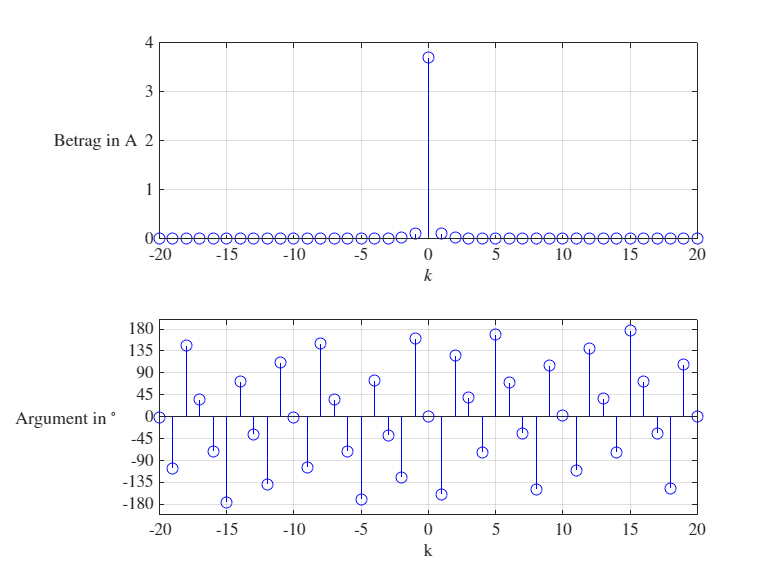

figure
tiledlayout(2, 1)

nexttile
stem(i_RL.frsp_idx, i_RL.frsp_amp, 'b')

grid('on')
xlim([-i_RL.frsp_n, i_RL.frsp_n])
xlabel('$k$')
ylabel('Betrag in A')
set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')

nexttile
stem(i_RL.frsp_idx, i_RL.frsp_arg, 'b')

grid('on')
xlim([-i_RL.frsp_n, i_RL.frsp_n])
ylim([-200, 200])
set(gca, 'YTick', -180 : 45 : 180)
xlabel('k')
ylabel('Argument in $^\circ$')
set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')

Frequenzspektrum der Eingangsspannung 

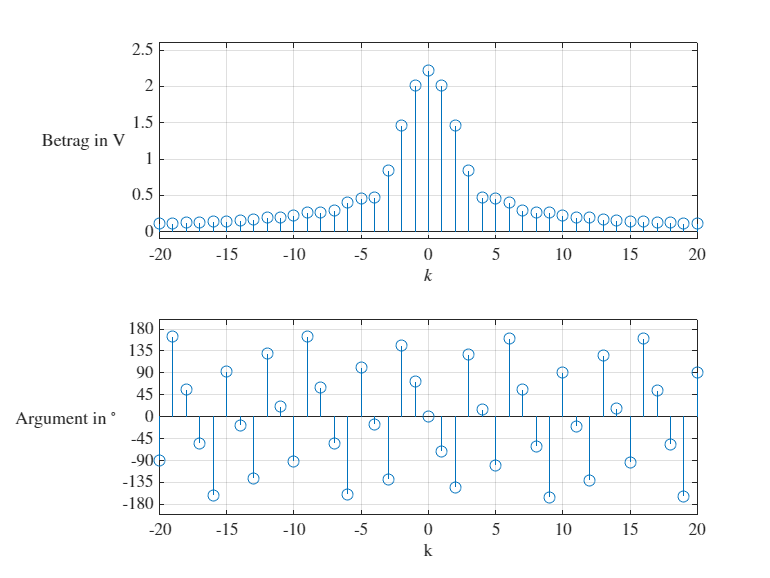

figure
tiledlayout(2, 1)

nexttile
stem(u_p.frsp_idx, u_p.frsp_amp)

grid('on')
xlim([-u_p.frsp_n, u_p.frsp_n])
ylim([-0.1, 2.6])
xlabel('$k$')
ylabel('Betrag in V')
set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')

nexttile
stem(u_p.frsp_idx, u_p.frsp_arg)

grid('on')
xlim([-u_p.frsp_n, u_p.frsp_n])
ylim([-200, 200])
set(gca, 'YTick', -180 : 45 : 180)
xlabel('k')
ylabel('Argument in $^\circ$')
set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')

Im Plot lässt sich das Tiefpass Verhalten der Spule erkennen, der Strom des Gleichanteil ist sehr viel größer als bei Grundschwingung und Oberschwingungen. 

Auch kann man erkennnen, dass es für gleiche k das Argument des Stroms um -90 ° versetzt ist, im Vergleich zum Argument der Spannungen.

## **Grafische Darstellung der Stromstärke **

i_RL.synth_n = 1000;
i_RL.i_k_synth = [i_RL.i_k(1), double(subs(i_RL_k_num, k, 1 : i_RL.synth_n))];
i_RL.i_Amp_Mat = repmat(i_RL.i_k_synth.', [1, length(u_p.t)]);
i_RL.Harm_Komp_Mat = i_RL.i_Amp_Mat .* exp(1j * 2 * pi / u_p.T * (0 : i_RL.synth_n)' * u_p.t);
i_RL.Harm_Mat = zeros(size(i_RL.Harm_Komp_Mat));
i_RL.Harm_Mat(1, :) = i_RL.Harm_Komp_Mat(1, :);
i_RL.Harm_Mat(2 : end, :) = i_RL.Harm_Komp_Mat(2 : end, :) + conj(i_RL.Harm_Komp_Mat(2 : end, :));
i_RL.part_Mat = cumsum(i_RL.Harm_Mat, 1);

Durch den hohen Gleichanteil bewegt sich die Stromstärke zwischen 3.4 und 4 Ampere

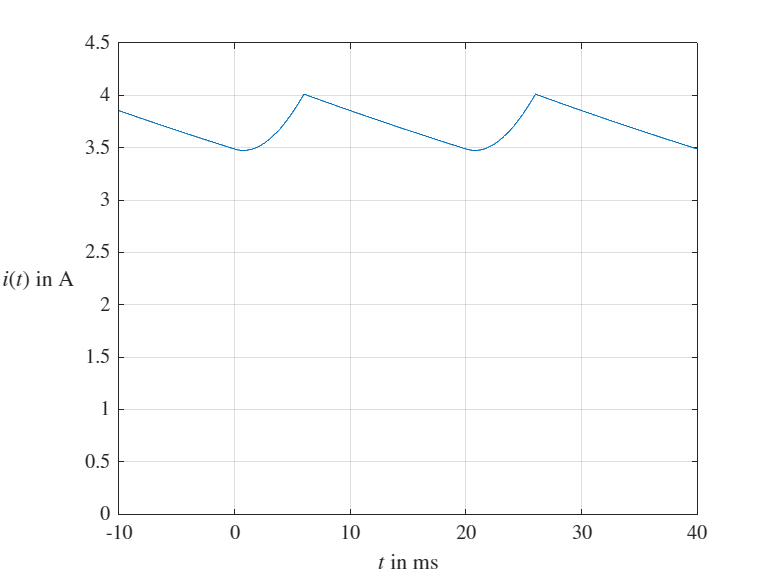

figure

plot(u_p.t * 1e3, i_RL.part_Mat(end, :))
ylim([0, 4.5])
xlim([u_p.t(1) * 1e3, u_p.t(end) * 1e3])
grid('on')
xlabel('$t$ in ms')
ylabel('$i(t)$ in A')
set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')

Bei einer genaueren betrachtung sind die periodischen Schwingungen gut erkennbar:

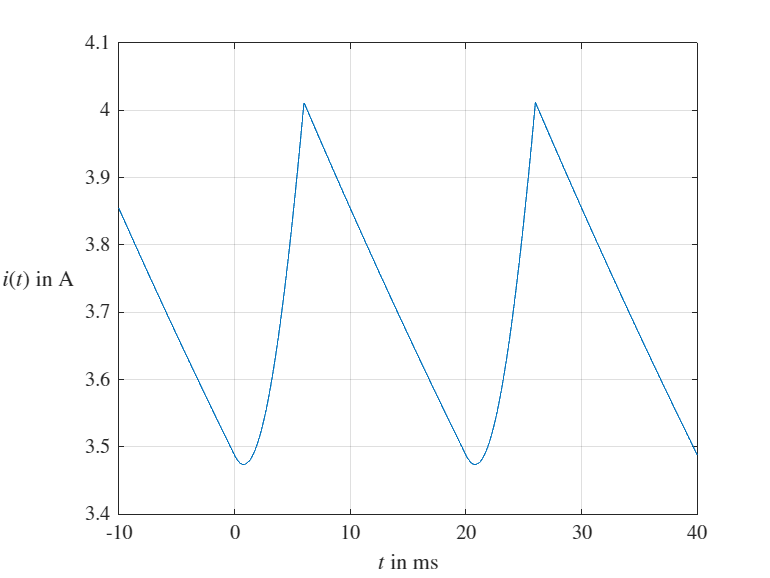

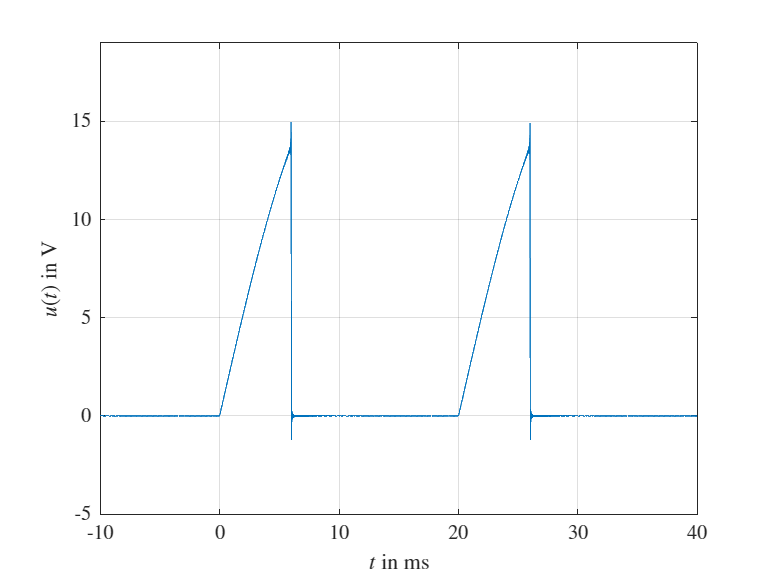

figure

plot(u_p.t * 1e3, i_RL.part_Mat(end, :))
xlim([u_p.t(1) * 1e3, u_p.t(end) * 1e3])
grid('on')
xlabel('$t$ in ms')
ylabel('$i(t)$ in A')
set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')

Die Stromstärke erreicht ihr Maximum zu jenem Zeitpunkt wo die Sinushalbwelle auf 0 geschalten wird, dannach nimmt die Stromstärke konstant ab. Es ist auch erkennbar, dass der Anstieg der Stromstärke im Vergleich zum Spannungsanstieg leicht verzögert ist, wie bei einer RL Schaltung zu erwarten.

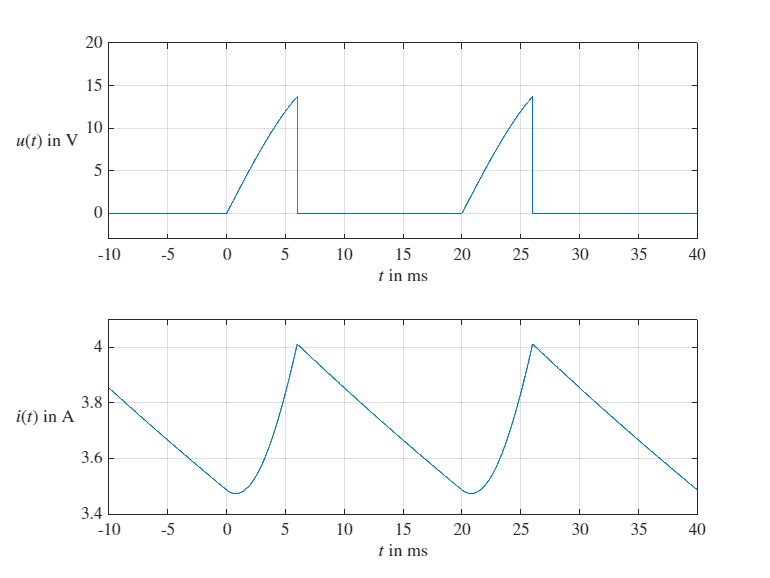

figure
tiledlayout(2, 1)

nexttile
plot(u_p.t * 1e3, u_p.u_t)

grid('on')
xlim([u_p.t(1) * 1e3, u_p.t(end) * 1e3])
ylim([-3,20])
xlabel('$t$ in ms')
ylabel('$u(t)$ in V')
set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')

nexttile
plot(u_p.t * 1e3, i_RL.part_Mat(end, :))

grid('on')
xlim([u_p.t(1) * 1e3, u_p.t(end) * 1e3])
ylim([3.4,4.1])

xlabel('$t$ in ms')
ylabel('$i(t)$ in A')
set(get(gca, 'ylabel'), 'Rotation', 0, 'HorizontalAlignment', 'right', 'VerticalAlignment', 'middle')

## **Bestimmung Kenngrößen **